clear

staticP = zeros(1,11);
totalP = zeros(1, 7);

for i = (1:7)
    data = load("231012_Group05_Supersonic_Total_"+i+".mat");
    
    t = (1:2500);
    
    %data.dataP_mean
    
    %swapping 4 & 5: 
    v = data.dataP_mean(:,4);
    data.dataP_mean(:, 4) = data.dataP_mean(:, 5);
    data.dataP_mean(:, 5) = v;
    
    %swapping 10 & 11: 
    v = data.dataP_mean(:,10);
    data.dataP_mean(:, 10) = data.dataP_mean(:, 11);
    data.dataP_mean(:, 11) = v;
    
    %data.dataP_mean
    %plot(t, dataP_mean);

    staticP = staticP + data.dataP_mean(1:11);
    totalP(i) = data.dataP_mean(12);
    
    %avgP = data.dataP_mean;
    %x = (1:10);
    %plot(x, avgP(1:10))
    %hold on;

    clear data

end

staticP = staticP/7;
totalP;

x = [24.7, 36.6, 48.3, 61.0, 73.7, 86.4, 99.1, 118, 209.5, 300.1];
% plot(x(1:7),totalP) 
% hold on;
% plot(x(1:7),staticP(1:7))
% hold off;

g = 1.4

g = 1.4000

M_exp = zeros(1,7);
m_err_exp = zeros(1,7);

syms M

for i = (1:7)
    eqn = @(M) ((((g+1)/2)*M^2)^(g/(g-1)))*((2*g/(g+1))*M^2 - (g-1)/(g+1))^(-1/(g-1)) - totalP(i)/staticP(i);
    [M_exp(i), m_err_exp(i)] = (fzero(eqn, 0.6*i));
end

pt_err = 0.005*103421;

p_err_ex = ones(1,7)*pt_err

p_err_ex =   517.1050  517.1050  517.1050  517.1050  517.1050  517.1050  517.1050



m_err_ex = zeros(1,7);

P = zeros(2, 7);
P_error = ones(2, 7);
y = 1.4;

P(1, :) = staticP(1:7);
P(2, :) = totalP;
P_error = P_error * pt_err;

[M_theo, m_err_theo, p_theo, p_err_theo] = subsonic_theo(P, P_error, y)

M_theo =     0.7544    1.0000    1.2589    1.4598    1.5744    1.6240    1.6359


m_err_theo = 1.0e-15 *

    0.2220         0   -0.4441   -0.4441    0.2220    0.2220    0.2220


p_theo = 1.0e+04 *

    6.9201    5.3313    3.8499    2.9131    2.4660    2.2910    2.2511


p_err_theo =   354.5880  273.1772  197.2719  149.2685  126.3572  117.3936  115.3446


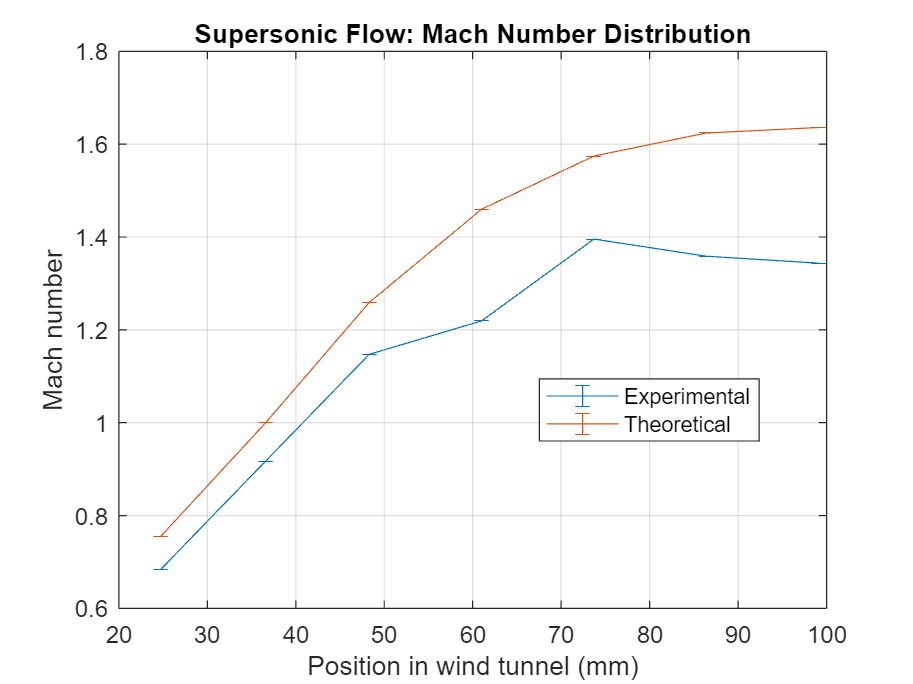


%hold on;
grid on;

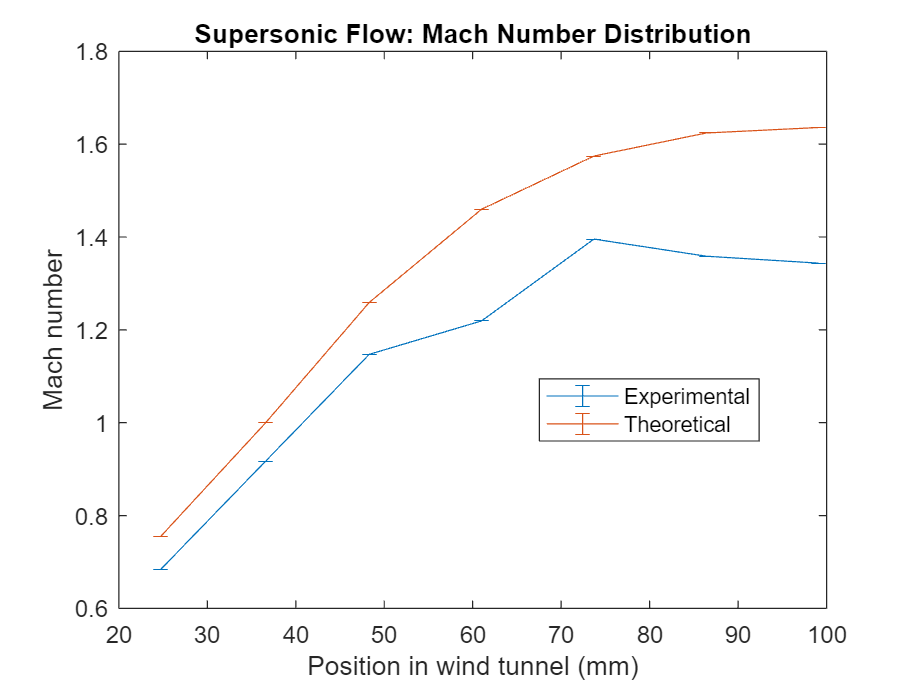

pl1 = errorbar(x(1:7), M_exp, m_err_ex);
hold on;
pl2 = errorbar(x(1:7), M_theo, m_err_theo);
title("Supersonic Flow: Mach Number Distribution")
legend([pl1(1) pl2(1)],{'Experimental','Theoretical'},'location','best');
xlabel("Position in wind tunnel (mm)");
ylabel("Mach number");
hold off;

grid on;

pl3 = errorbar(x(1:7), staticP(1:7), p_err_ex);
hold on;
pl4 = errorbar(x(1:7), p_theo, p_err_theo);
title("Supersonic Flow: Pressure Distribution")
legend([pl3(1) pl4(1)],{'Experimental','Theoretical'},'location','best');
xlabel("Position in wind tunnel (mm)");
ylabel("Pressure (Pa)");

hold off;

%clear
%load("231012_Group05_Subsonic_Total_1.mat")
%dataP
g = 1.4

g = 1.4000

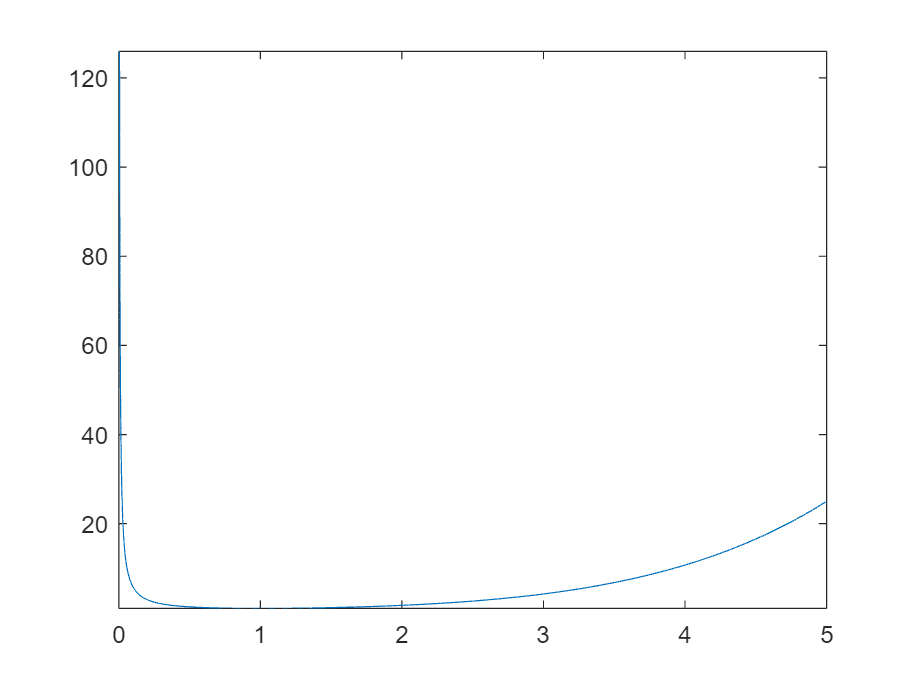


test= @(m) 1/m*( (2/(g+1)) * (1 + ((g-1)/2)*m^2) ) ^ ((g+1)/(2*g-2));

fplot(test, [0,5])

function [M, M_error, p, p_error] = subsonic_theo(P, P_error, g)
    %{
    Inputs
    P : matrix (2, 7)
        Static and total pressures corresponding to each position.
        (1,:): Static port pressures
        (2,:): Total pressures
    P_error : matrix (2, 7)
        Precision uncertainty of static and total pressures
        (1,:): Static port pressures
        (2,:): Total pressures
    g : float
        Ratio of specific heats (gamma).

    Returns
    M : matrix (1, 7)
        The Mach numbers for the input pressure data.
    M_error : matrix (1, 7)
        The Mach number uncertainties.
    p : matrix (1, 7)
        The pressure for the theoretical data.
    p_err : matrix(1, 7)
        Uncertainties associated with the pressures.
    %}

    Ar = [1.06, 1.00, 1.05, 1.15, 1.23, 1.27, 1.28];
    
    p_error = zeros(1, 7);
    p = zeros(1, 7);
    M = zeros(1,7);
    M_error = zeros(1,7);
    
    for i = 1:7
        f = @(m) (1/m*( (2/(g+1)) * (1 + ((g-1)/2)*m^2) ) ^ ((g+1)/(2*g-2))) - Ar(i);
        if i == 1
            % since flow will likely be subsonic before throat
            [M(i), M_error(i)] = fzero(f, 0.8);
        elseif i == 2
            % since flow will likely be just over Mach 1 at the second tap
            % since its the throat
            [M(i), M_error(i)] = fzero(f, 1);
        else 
            % Subsonic everywhere else
            [M(i), M_error(i)] = fzero(f, 2);
        end
    end
    
    h = @(m)(1 + (g - 1)./2 .*m.^2).^(-g ./(g - 1));
    
    p(1, :) = P(2,1) * h(M(1,:));
    
    dp = @(m)-(2.*m.*g*(g./2 - 1./2))./(((g./2 - 1./2).*m.^2 + 1) ...
        .^(g./(g - 1) + 1).*(g - 1));

    p_error = sqrt((h(M) .* P_error(2)).^2 + (dp(M) .* M_error).^2);

    
end